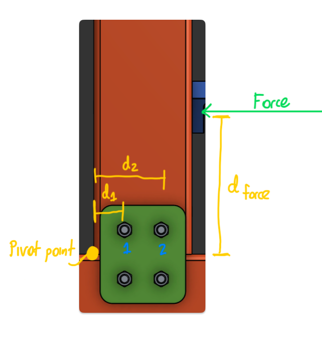

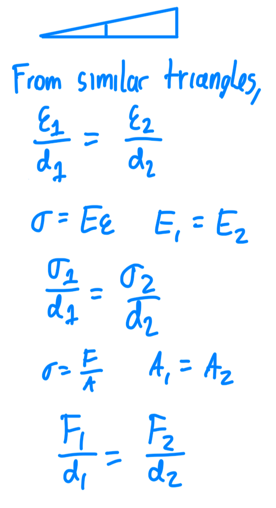

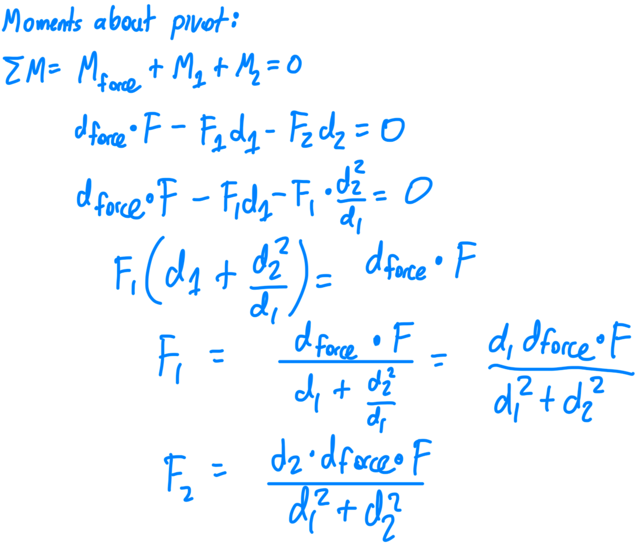

force    = 1000/1000; % kips
d_force  = 6; % in
d1       = 1; % in
d2       = 2.5 ; % in

t_gusset = 0.25; % in
t_spar   = 0.1875; % in

hole_dia = 0.375; % in

bolt_shear_strength   = 44; % ksi
spar_bearing_strength = 69.6; % ksi

f1 = d1*d_force*force/(d1^2+d2^2); % kips
f2 = d2*d_force*force/(d1^2+d2^2); % kips

% Two shear planes --------------------------v
bearing_stress_1 = f1/(hole_dia*t_spar)    / 2; % ksi
shear_stress_1   = f1/(.25*pi*hole_dia^2)  / 2; % ksi

bearing_stress_2 = f2/(hole_dia*t_spar)    / 2; % ksi
shear_stress_2   = f2/(.25*pi*hole_dia^2)  / 2; % ksi

showFOS("Hole 1 Bearing", spar_bearing_strength, bearing_stress_1, 'ksi');

Hole 1 Bearing            	Stress: 5.9 ksi 	FOS: 11.83

showFOS("Bolt 1 Shear", bolt_shear_strength, shear_stress_1, 'ksi');

Bolt 1 Shear              	Stress: 3.7 ksi 	FOS: 11.74


showFOS("Hole 2 Bearing", spar_bearing_strength, bearing_stress_2, 'ksi');

Hole 2 Bearing            	Stress: 14.7 ksi 	FOS: 4.73

showFOS("Bolt 2 Shear", bolt_shear_strength, shear_stress_2, 'ksi');

Bolt 2 Shear              	Stress: 9.4 ksi 	FOS: 4.70